# Assignment 1: CT reconstruction

## Make a phantom of size 256x256

phantomSize = 256;
P = phantom(phantomSize);

## Display Phantom image

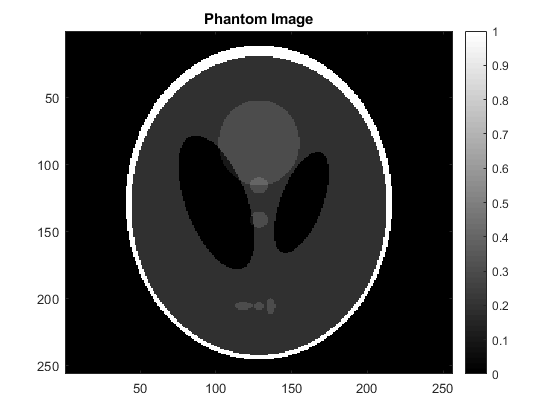

figure;
colormap('gray');
imagesc(P);
title('Phantom Image');
colorbar;

## Set parameters

numDetectorPixels = 500;  % Same as number of rays or number of parallel projections.
numReconPixels = 256;
numProjectionViews = 360;
scanningRange = 180;

increment = scanningRange/numProjectionViews;

% The thetas do not necessesarily have to be in this range.
% Just matching the angles for MATLAB's radon function.
originalThetas = 0:increment:scanningRange-increment;
thetas = originalThetas + 90;

assert(length(thetas) == numProjectionViews,...
    'Incorrect implementation of thetas! Watch your indexing!');
assert(numDetectorPixels >= numReconPixels,...
    'The reconstruction image cannot have a higher resolution than detector!');

## Zero-pad Phantom Image

Pad the image with zeros so that we don't lose anything when we rotate.

Padding assumes an even number of image (phantom) and detector pixels.

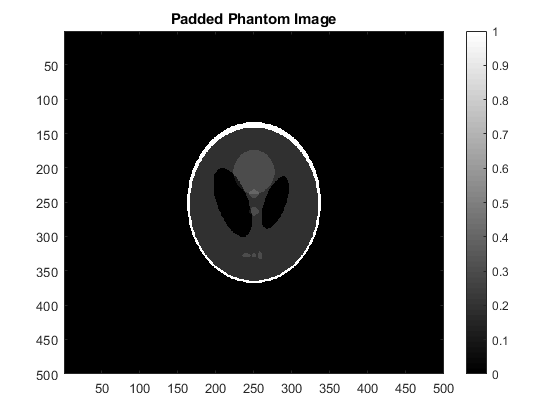

padsize = floor((numDetectorPixels - phantomSize) / 2);
paddedPhantom = padarray(P, [padsize, padsize], 0, 'both');

figure;
colormap('gray');
imagesc(paddedPhantom);
title('Padded Phantom Image');
colorbar;

## Shift Phantom Image

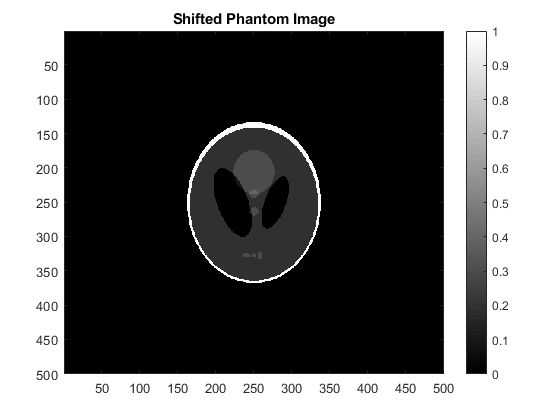

shift = [0, 0];  % Number of pixels to shift. Shift to bottom right by 'shift' pixels.
phantomImage = imtranslate(paddedPhantom, shift);

figure;
colormap('gray');
imagesc(phantomImage);
title('Shifted Phantom Image');
colorbar;

## Projection

Implement the Radon Transform using the imrotate function.

sinogram = zeros(numDetectorPixels, numProjectionViews);
for projection=1:numProjectionViews
    % Direction of theta may be opposite depending on which system one is using.
    rotated = imrotate(phantomImage, -thetas(projection), 'bilinear', 'crop');
    sinogram(:, projection) = sum(rotated, 2);
end

assert(isequal(size(sinogram), [numDetectorPixels, numProjectionViews]),...
    'Inaccurate output size.');

## Display Sinogram

The value labels on the axes of this image are different from those on the next sinogram.

Don't worry if they are different.

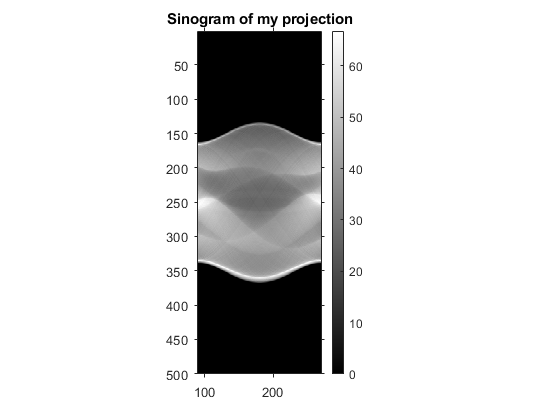

figure;
colormap('gray');
imshow(sinogram, [], 'Xdata', thetas, 'InitialMagnification', 'fit');
title('Sinogram of my projection');
colorbar;

## MATLAB native radon function.

See [here](https://www.mathworks.com/help/images/reconstructing-an-image-from-projection-data.html) for the example of how to use the radon transform and inverse radon transform in MATLAB.

See [here](https://www.mathworks.com/help/images/radon-transform.html) for information on the radon transform.

P.S. MATLAB's radon function has no variable for the number of detector pixels. This can be solved by cropping the resulting image from the radon function.

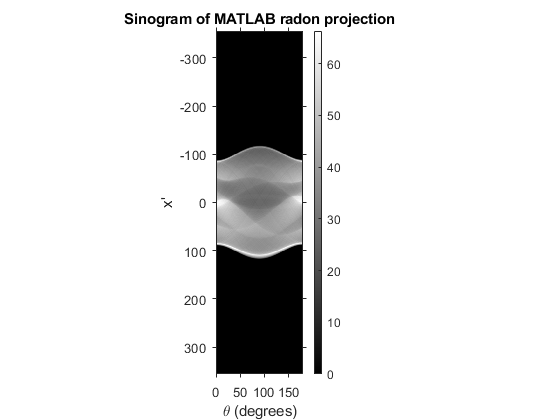

[R, xp] = radon(phantomImage, originalThetas);

figure;
colormap('gray');
imshow(R, [], 'Xdata', originalThetas, 'Ydata', xp, 'InitialMagnification', 'fit');
title('Sinogram of MATLAB radon projection');
iptsetpref('ImshowAxesVisible', 'on');
xlabel('\theta (degrees)');
ylabel('x''');
colorbar;

## Display sinogram difference image

Difference Image between the implemented projection and MATLAB's radon function.

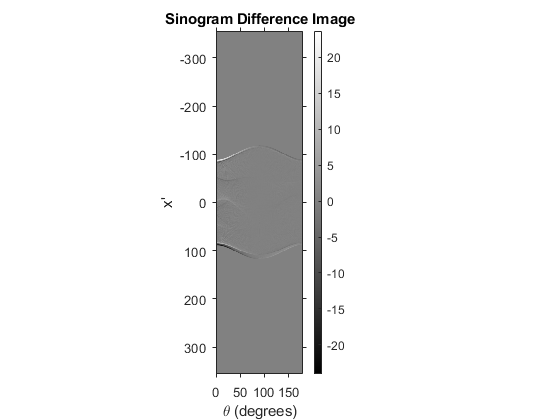

prePad = floor((norm(size(phantomImage)) - numDetectorPixels) / 2) + 2;
postPad = ceil((norm(size(phantomImage)) - numDetectorPixels) / 2) + 2;

paddedSinogram = padarray(sinogram, prePad, 0, 'pre');
paddedSinogram = padarray(paddedSinogram, postPad, 0, 'post');
DiffSinogram = paddedSinogram - R;

figure;
colormap('gray');
imshow(DiffSinogram, [], 'Xdata', originalThetas, 'Ydata', xp, 'InitialMagnification', 'fit');
title('Sinogram Difference Image');
iptsetpref('ImshowAxesVisible', 'on')
xlabel('\theta (degrees)');
ylabel('x''');
colorbar;

## Filtering

The Ram-Lak filter, a.k.a. the Ramp filter, simply uses the absolute value of the frequency as the filter. 

rampFilter = 0:numDetectorPixels-1;  % Take out the last value.
rampFilter = rampFilter - floor(numDetectorPixels/2);
rampFilter = abs(rampFilter)' / (numDetectorPixels/2);  % Rescale the ramp filter to abs(-1 ~ 1).
repRampFilter = repmat(rampFilter, 1, numProjectionViews);  % Expand the ramp filter for element-wise multiplication.

assert(isequal(size(repRampFilter), size(sinogram)), 'Please check Ramp filter size.');
assert(isequal(rampFilter, repRampFilter(:, 1)), 'Something went wrong. Try repmat.');

minimal = 0 <= min(repRampFilter, [], 'all');
maximal = max(repRampFilter, [], 'all') <= 1;
assert((minimal & maximal), 'The filter should be scaled between 0~1.')

% Don't forget to use fftshift and ifftshift!
filteredProfile = repRampFilter .* ifftshift(fft(fftshift(sinogram), [], 1));  % FFT along dim 1.
filteredProjection = ifftshift(ifft(fftshift(filteredProfile), [], 1));  % IFFT back to spatial domain.
filteredProjection = real(filteredProjection);

## Show filtered sinogram

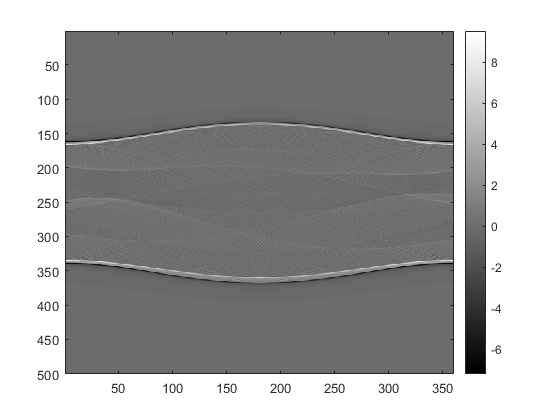

figure;
imagesc(filteredProjection);
colormap('gray');
colorbar;

## Backprojection

Implementing backprojection using imrotate.

See [here](https://www.mathworks.com/help/images/the-inverse-radon-transformation.html) for a simple explanation of backprojection.

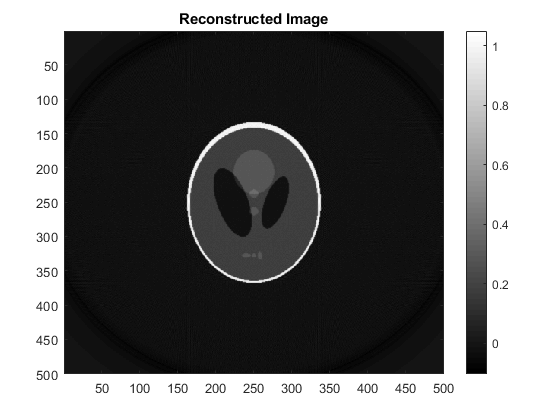

scalingFactor = scanningRange .* 2 .* pi / (increment .* 10);
backProjectedImage = zeros(numDetectorPixels, numDetectorPixels);

for projection=1:numProjectionViews    
    temp = repmat(filteredProjection(:, projection), 1, numDetectorPixels) / scalingFactor;    
    temp = imrotate(temp, thetas(projection), 'bilinear', 'crop');
    backProjectedImage = backProjectedImage + temp;
end

assert(isequal(size(backProjectedImage), [numDetectorPixels, numDetectorPixels]),...
    'Backprojected image has incorrect size. Do not fit to reconstruction image size yet.');
figure;
colormap('gray');
imagesc(backProjectedImage);
title('Reconstructed Image');
colorbar;

## Crop and display Backprojected image

Cropping to fit the number of pixels in the reconstruction image. 

This code assumes an even number of detector and reconstruction pixel number.

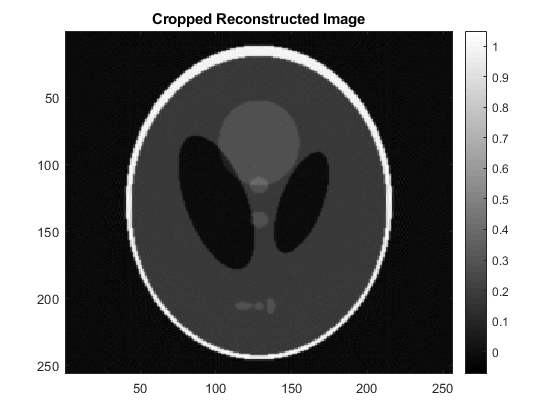

top = floor((numDetectorPixels-numReconPixels)/2) + 1;
left = floor((numDetectorPixels-numReconPixels)/2) + 1;

reconstructedImage = imcrop(backProjectedImage, [left, top, numReconPixels - 1, numReconPixels - 1]);

assert(isequal(size(reconstructedImage), [numReconPixels, numReconPixels]),...
    'Reconstruction image has incorrect size. Check indexing.');

figure;
imagesc(reconstructedImage);
title('Cropped Reconstructed Image');
colormap('gray');
colorbar;

## Reconstruction Difference Image

Checking difference from phantom image.

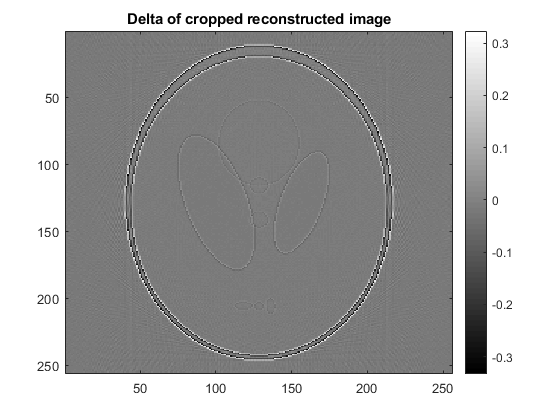

croppedPhantom = imcrop(phantomImage, [left, top, numReconPixels-1, numReconPixels-1]);
myDelta = reconstructedImage - croppedPhantom;

figure;
colormap('gray');
imagesc(myDelta);
title('Delta of cropped reconstructed image');
colorbar;

## MATLAB native iradon function

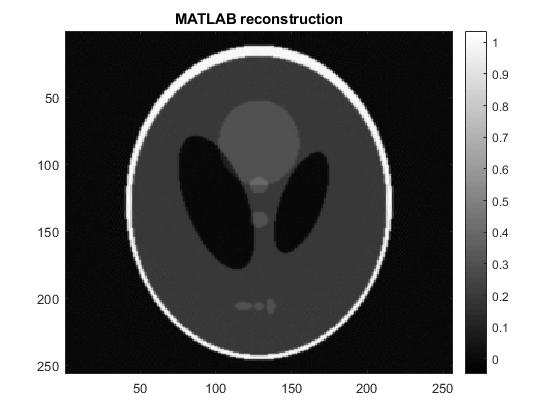

paddedInverseRadon = iradon(R, originalThetas, 'linear', 'Ram-Lak', 1, numReconPixels);
figure;
imagesc(paddedInverseRadon);
title('MATLAB reconstruction')
colormap('gray');
colorbar;

## MATLAB delta

Display difference image for MATLAB radon-iradon with original phantom.

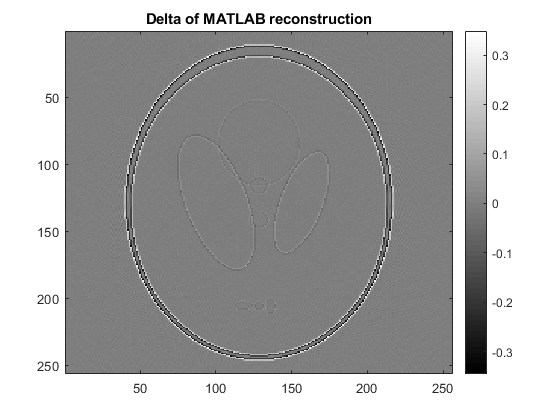

matlabDelta = paddedInverseRadon - croppedPhantom;

figure;
imagesc(matlabDelta);
title('Delta of MATLAB reconstruction');
colormap('gray');
colorbar;

## Display all results

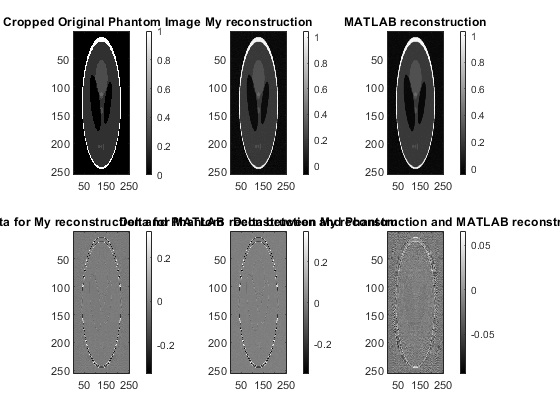

figure;
colormap('gray');

subplot(2, 3, 1);
imagesc(croppedPhantom);
colorbar;
title('Cropped Original Phantom Image');

subplot(2, 3, 2);
imagesc(reconstructedImage);
colorbar;
title('My reconstruction');

subplot(2, 3, 3);
imagesc(paddedInverseRadon);
colorbar;
title('MATLAB reconstruction');

subplot(2, 3, 4);
imagesc(myDelta);
colorbar;
title('Delta for My reconstruction and Phantom');


subplot(2, 3, 5);
imagesc(matlabDelta);
colorbar;
title('Delta for MATLAB reconstruction and Phantom');


subplot(2, 3, 6);
imagesc(reconstructedImage - paddedInverseRadon);
colorbar;
title('Delta between My reconstruction and MATLAB reconstruction');